% Clear variables, figures
clear;
clf;
clc;

% Run script
run('master_thesis_script.m');

Building with 'Xcode with Clang'.
MEX completed successfully.
Building with 'Xcode with Clang'.
MEX completed successfully.
Building with 'Xcode with Clang'.
MEX completed successfully.
Building with 'Xcode with Clang'.
MEX completed successfully.


# LS APPROACH


$$\dot{q} = J^{\dagger}(q) \cdot  u  \qquad \longrightarrow \qquad u = \dot{p}$$


#### FORWARD KINEMATICS


$$\pmatrix{p_{1} \cr P_{2} \cr .. \cr P_{M}} = \pmatrix{\Phi_1(q) \cr \Phi_2(q) \cr ..  \cr \Phi_M(q) } \qquad \Longrightarrow \qquad  p = \Phi(q)$$


#### JACOBIAN COMPUTATION


$$\pmatrix{\dot{p}_{1} \cr \dot{p}_{2} \cr .. \cr \dot{p}_{M}} = \pmatrix{J_1(q) \cr J_2(q) \cr ..  \cr J_M(q) } \cdot \dot{q} \qquad \Longrightarrow \qquad  \dot{p} = J(q) \cdot  \dot{q} $$


## 1.  PERFECT GUESS OF INITIAL CONDITION q0 

% Initial CORRECT joint variables estimate used by LS
LS.q0 = [0;
         0;
         0;
         0;
         0;
         0;
         0];

### 1.1 SMALLER NOISE vs LARGER NOISE affecting pdot

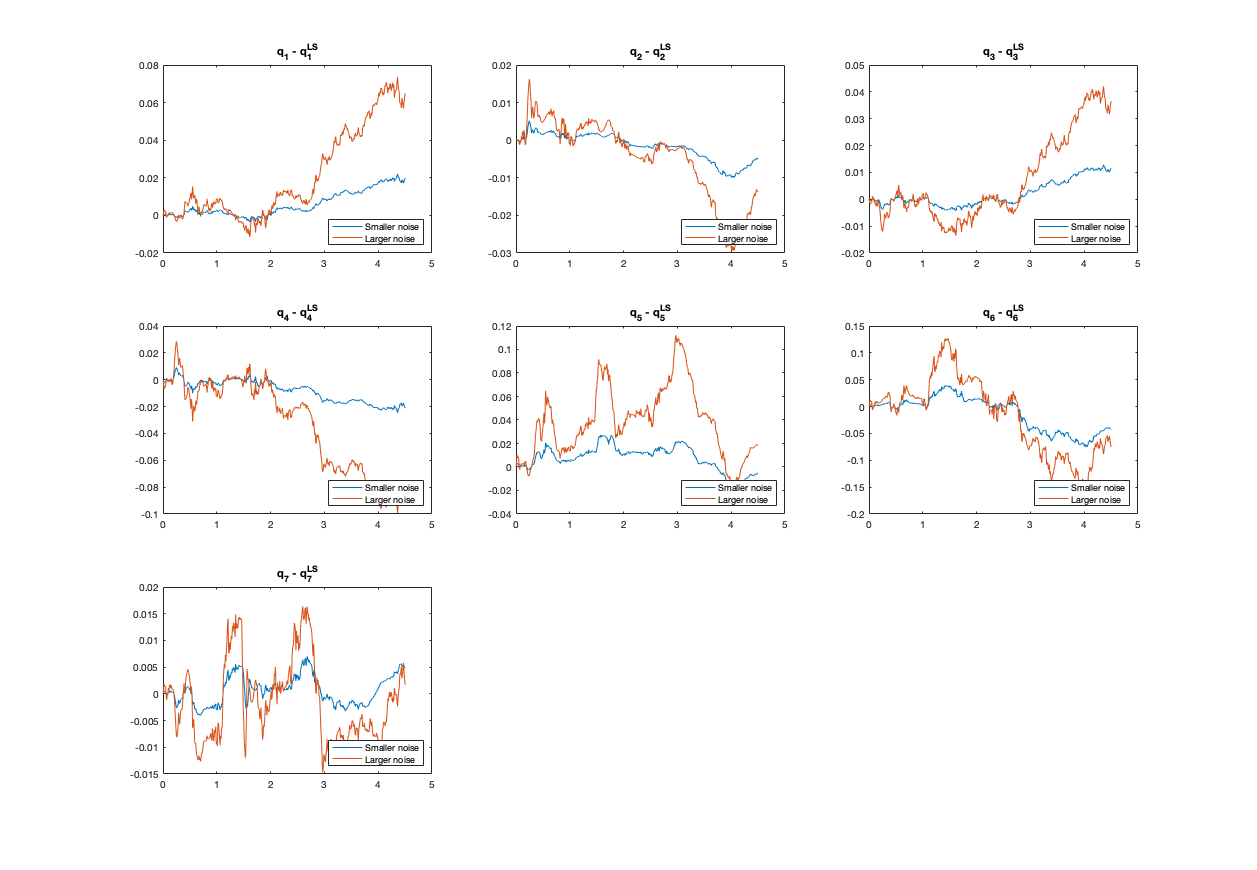

% Noise affecting pdot measurements
noise.pdot_var = 0.0000001 * ones(m * 3, 1);
% Simulation
output_1 = sim("master_thesis_simulink.slx");

% Noise affecting pdot measurements
noise.pdot_var = 0.000001 * ones(m * 3, 1);
% Simulation
output_2 = sim("master_thesis_simulink.slx");

% Plot error between q_LS and q (comparison between smaller noise and larger noise)
title_name = cell(n, 1);
fig_1 = figure(1);
for i = 1 : n

    title_name{i} = strcat('q_', num2str(i), ' - q_', num2str(i), '^{LS}');
    set(fig_1, 'position', [10, 10, 1300, 900]);
    subplot(3,3,i);
    plot(output_1.q.time, rad2deg(output_1.q.signals.values(:, i) - squeeze(output_1.q_LS.signals.values(i, :))'));
    hold on;
    plot(output_2.q.time, rad2deg(output_2.q.signals.values(:, i) - squeeze(output_2.q_LS.signals.values(i, :))'));
    legend('Smaller noise', 'Larger noise', 'Location', 'southeast');
    title(title_name{i});
end

## 2.  WRONG GUESS OF INITIAL CONDITION q0

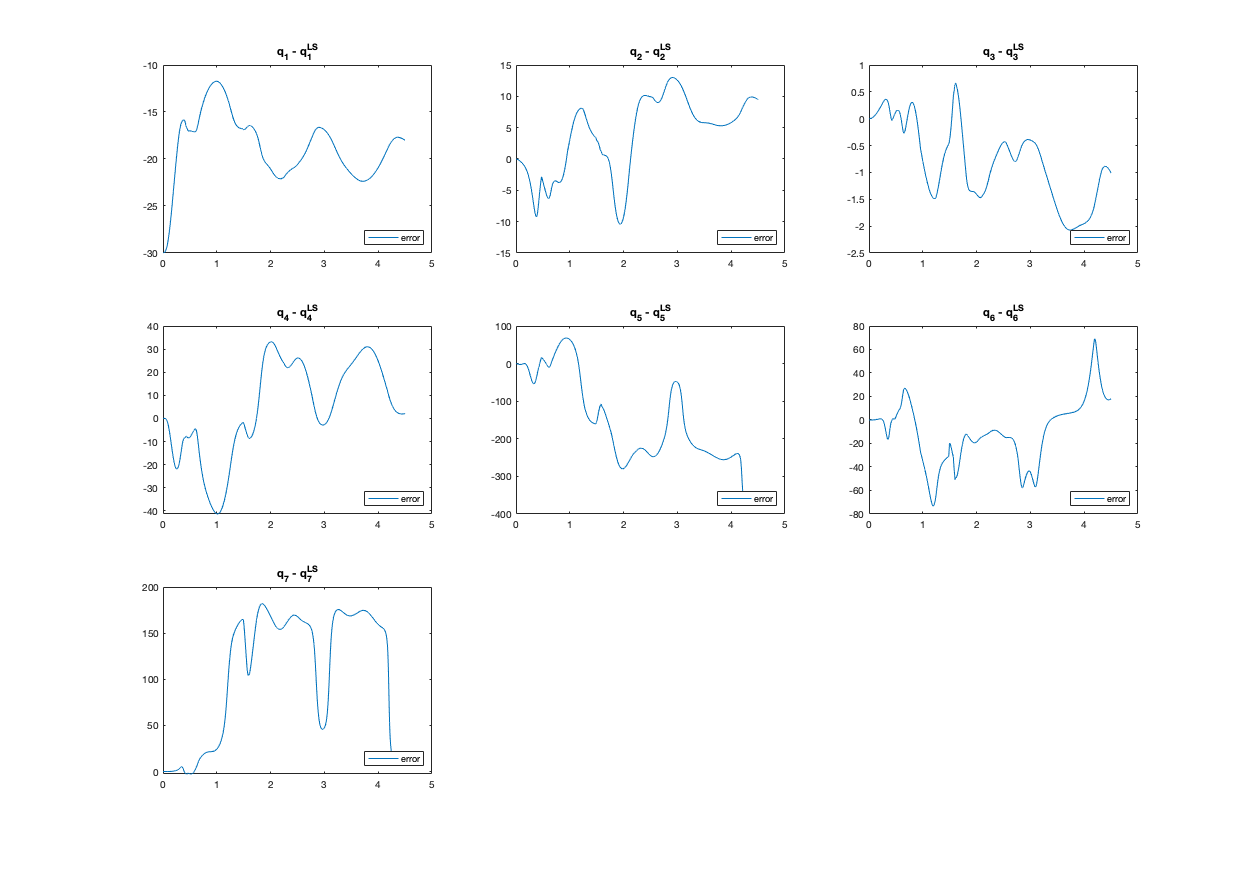

% Initial WRONG joint variables estimate used by LS
LS.q0 = [pi/6;
         0;
         0;
         0;
         0;
         0;
         0];

% Noise affecting pdot measurements
noise.pdot_var = 0.0000001 * ones(m * 3, 1);

% Simulation
output_3 = sim("master_thesis_simulink.slx");

% Plot error between q_LS and q
fig_3 = figure(3);
for i = 1 : n

    title_name{i} = strcat('q_', num2str(i), ' - q_', num2str(i), '^{LS}');
    set(fig_3, 'position', [10, 10, 1300, 900]);
    subplot(3,3,i);
    plot(output_3.q.time, rad2deg(output_3.q.signals.values(:, i) - squeeze(output_3.q_LS.signals.values(i, :))'));
    legend('error', 'Location', 'southeast');
    title(title_name{i});
end

# KALMAN FILTER ON LINEARIZED DISCRETE STATE-SPACE MODEL

## 1.  Discrete Non Linear model (Ts = 10ms)

Runge-Kutta discretization method is applied to the continuos NL model. The sampling time Ts = 10ms was chosen.


$$q_{k+1} = \textbf{f}(q_k, u_k) \qquad , \textbf{f} = q_k + \frac{1}{6}  \cdot T_s  \cdot (k_1 + 2k_2 + 2k_3 + k_4)  \\
p_k = \mathbf{\Phi}(q_k) \\
\\
\\
k_1 = J^{\dagger}(q_k)\cdot u_k  \\
k_2 = J^{\dagger}(q_k + T_s  \cdot  \frac{k_1}{2})\cdot u_k  \\
k_3 = J^{\dagger}(q_k + T_s  \cdot  \frac{k_2}{2})\cdot u_k  \\
k_4 = J^{\dagger}(q_k + T_s  \cdot  k_3)\cdot u_k$$


The comparison between the simulation and the discrete Non Linear model is reported below.

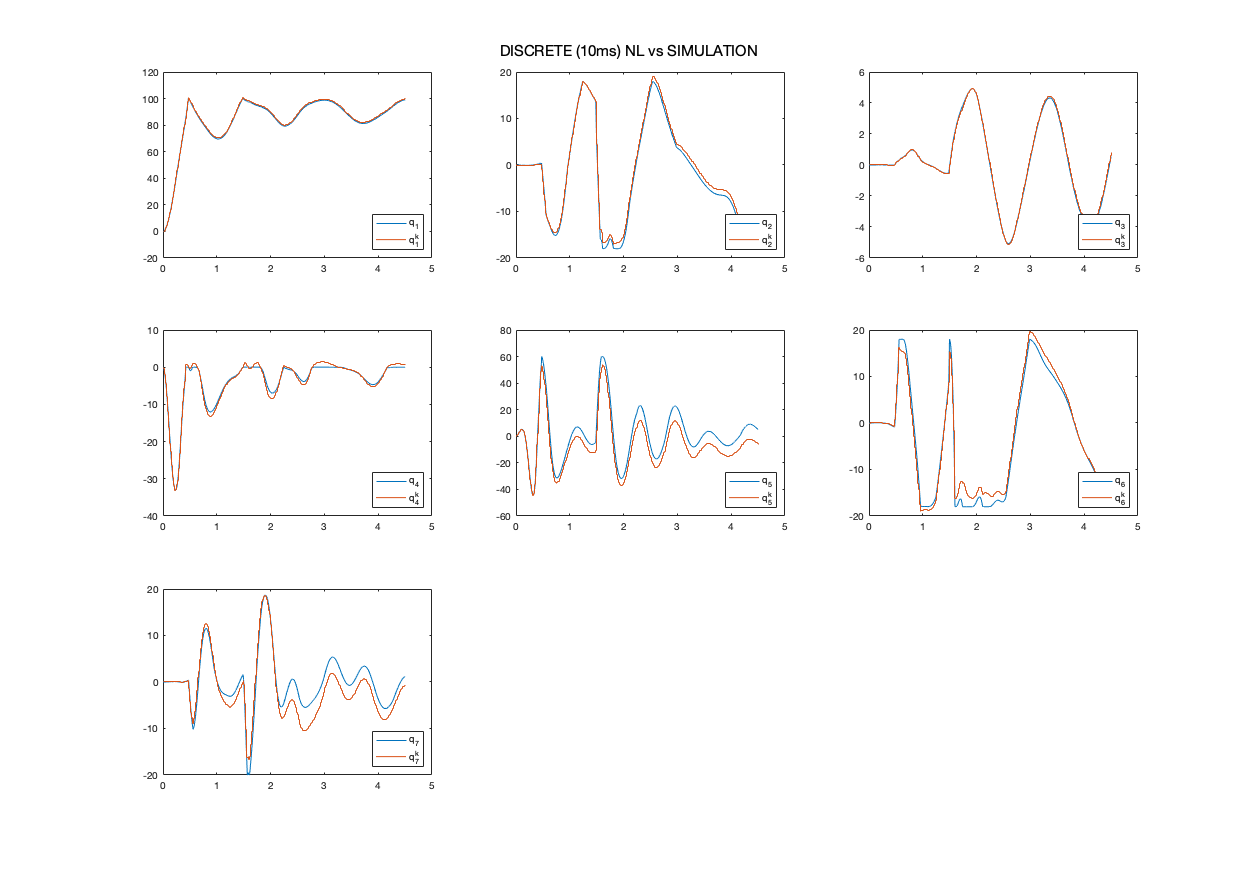

% Sampling time
sample_Time = 0.01;

% Simulation
output_4 = sim("master_thesis_simulink.slx");

% Plot DISCRETE vs CONTINUOS joints' variables (q vs qk)
fig_4 = figure(4);
sgtitle("DISCRETE (10ms) NL vs SIMULATION");
for i = 1 : n

    q = strcat('q_', num2str(i));
    qk = strcat('q^k_', num2str(i));
    set(fig_4, 'position', [10, 10, 1300, 900]);
    subplot(3,3,i);
    plot(output_4.q.time, rad2deg(output_4.q.signals.values(:, i)));
    hold on;
    stairs(output_4.qk.time, rad2deg(squeeze(output_4.qk.signals.values(i, :))'));
    legend(q, qk, 'Location', 'southeast');
end

## 2.  Linearized Discrete model around equilibrium point


$$q_{k+1} = A\cdot q_k + B\cdot u_k  \\
p_k = C\cdot q_k \\
\\
\\
A = \nabla_q\textbf{f}|_{q_{eq}, u_{eq}} \\
B = \nabla_u\textbf{f}|_{q_{eq}, u_{eq}} \\
C = \nabla_q\mathbf{\Phi}|_{q_{eq}}$$


### 2.1 Free fall motion, eq. point (q_eq = 0, u_eq = 0)

The discrete NL model, linearized around the equilibrium point q_eq, u_eq = 0, is expected to simulate very poorly the human arm free fall motion.

The comparison between simulation and linearized discrete state-space is reported below.

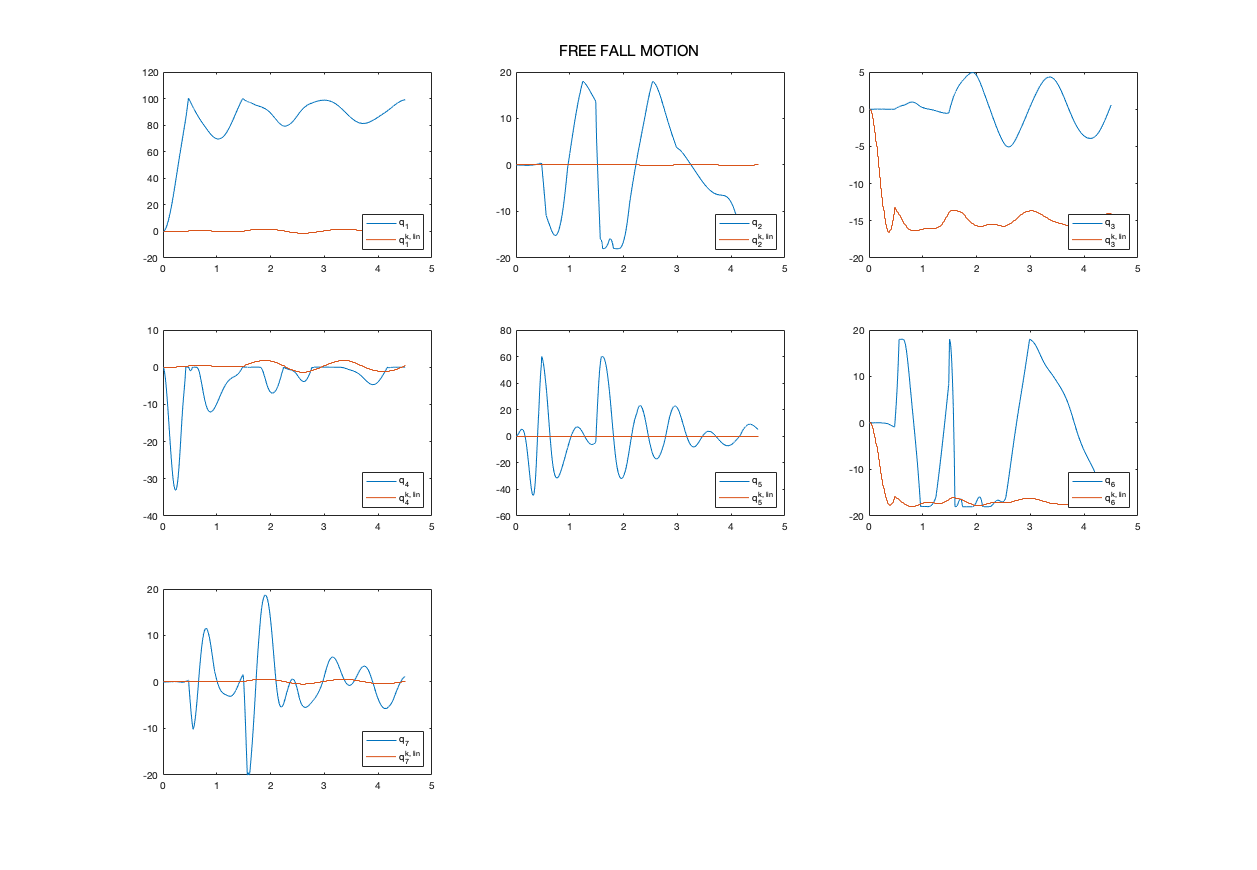

% Sampling time
sample_Time = 0.01;

% Human Arm IC SIMULATION
simulation.q0 = zeros(n, 1);

% Equilibrium point
equilibrium.q = zeros(n, 1);
equilibrium.u = zeros(3*m, 1);

% A matrix --> df/dq evaluated at the equilibrium point q_eq = 0, u_eq = 0
discrete_linearized.A = full(f_A(equilibrium.q, marker.shoulder_variables, marker.forearm_variables, marker.hand_variables, equilibrium.u));
% B matrix --> df/du evaluated at the equilibrium point q_eq = 0, u_eq = 0
discrete_linearized.B = full(f_B(equilibrium.q, marker.shoulder_variables, marker.forearm_variables, marker.hand_variables, equilibrium.u));

% C matrix --> dPhi/dq (Jacobian J) evaluated at the equilibrium point q_eq = 0
discrete_linearized.C = full(f_J(equilibrium.q, marker.shoulder_variables, marker.forearm_variables, marker.hand_variables));
% D matrix --> dPhi/du = 0 evaluated at the equilibrium point q_eq = 0, u_eq = 0
discrete_linearized.D = zeros(3*m, 3*m);

% Discrete State-Space model IC
discrete_linearized.q0 = simulation.q0;

% Simulation
output_5 = sim("master_thesis_simulink.slx");

% Plot DISCRETE LINEARIZED vs CONTINUOS joints' variables (q vs qklin)
fig_5 = figure(5);
sgtitle("FREE FALL MOTION");
for i = 1 : n

    q = strcat('q_', num2str(i));
    qk = strcat('q^{k, lin}_', num2str(i));
    set(fig_5, 'position', [10, 10, 1300, 900]);
    subplot(3,3,i);
    plot(output_5.q.time, rad2deg(output_5.q.signals.values(:, i)));
    hold on;
    stairs(output_5.qk_lin.time, rad2deg(squeeze(output_5.qk_lin.signals.values(:, i))'));
    legend(q, qk, 'Location', 'southeast');
end

### 2.2 Human arm motion close to the rest position

The discrete NL model is now linearized around the rest position of the human arm


$$q_0 = \pmatrix{85\degree  \cr 0\degree  \cr ..  \cr 0\degree } , \qquad q_{eq} =  \pmatrix{90 \degree  \cr 0\degree  \cr ..  \cr 0\degree },  \qquad u_{eq} =  \pmatrix{ 0  \cr 0  \cr ..  \cr 0 } $$


It is now expected to simulate better the human arm motion.

The comparison between simulation and linearized discrete state-space is reported below.

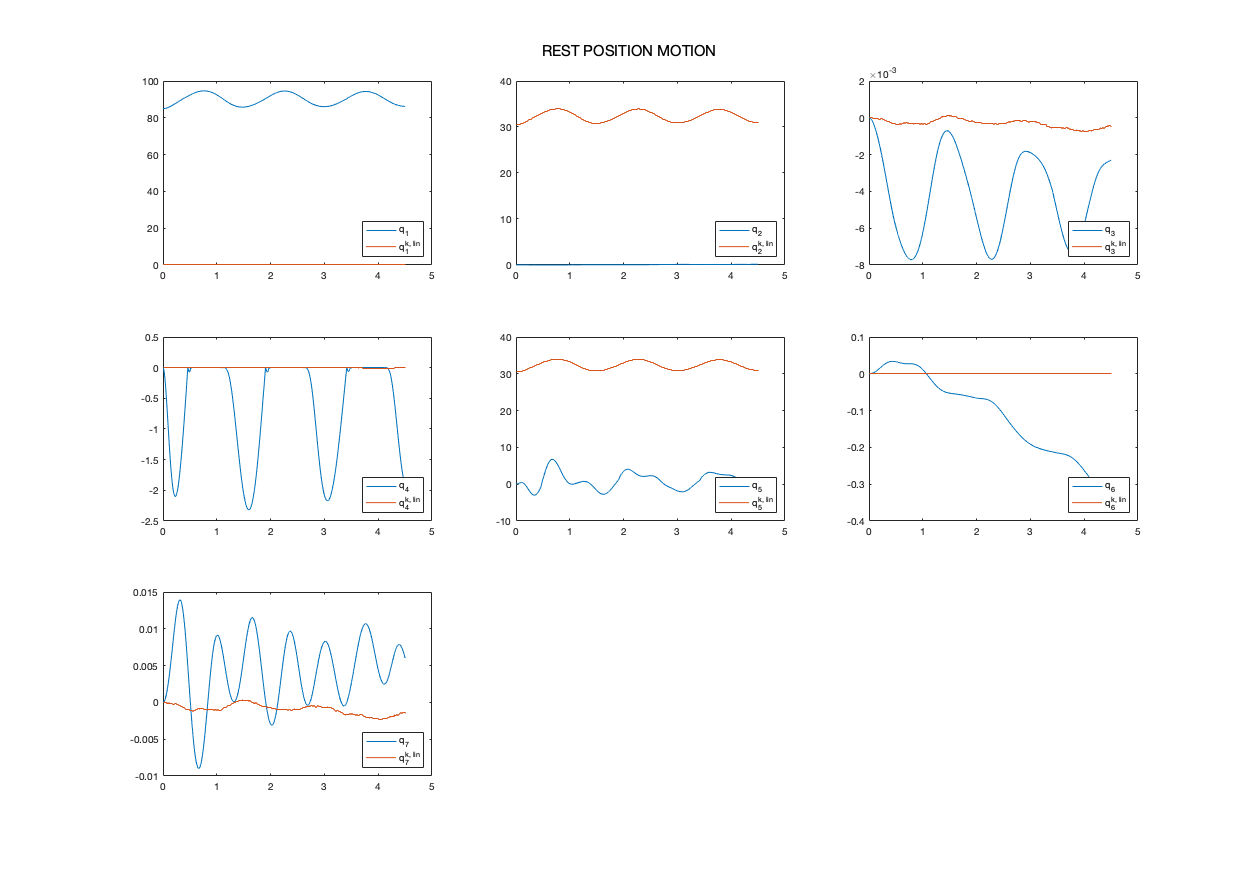

% Sampling time
sample_Time = 0.01;

% Human Arm IC SIMULATION [deg]
simulation.q0 = [deg2rad(85); zeros(n-1, 1)];

% Equilibrium point
equilibrium.q = [pi/2; zeros(n-1, 1)];
equilibrium.u = zeros(3*m, 1);

% A matrix --> df/dq evaluated at the equilibrium point q_eq = 0, u_eq = 0
discrete_linearized.A = full(f_A(equilibrium.q, marker.shoulder_variables, marker.forearm_variables, marker.hand_variables, equilibrium.u));
% B matrix --> df/du evaluated at the equilibrium point q_eq = 0, u_eq = 0
discrete_linearized.B = full(f_B(equilibrium.q, marker.shoulder_variables, marker.forearm_variables, marker.hand_variables, equilibrium.u));

% C matrix --> dPhi/dq (Jacobian J) evaluated at the equilibrium point q_eq = 0
discrete_linearized.C = full(f_J(equilibrium.q, marker.shoulder_variables, marker.forearm_variables, marker.hand_variables));
% D matrix --> dPhi/du = 0 evaluated at the equilibrium point q_eq = 0, u_eq = 0
discrete_linearized.D = zeros(3*m, 3*m);

% Set initial condition
discrete_linearized.q0 = [deg2rad(85); zeros(n-1, 1)];

% Simulation
output_6 = sim("master_thesis_simulink.slx");

% Plot DISCRETE LINEARIZED vs CONTINUOS joints' variables (q vs qklin)
fig_6 = figure(6);
sgtitle("REST POSITION MOTION");
for i = 1 : n

    q = strcat('q_', num2str(i));
    qk = strcat('q^{k, lin}_', num2str(i));
    set(fig_6, 'position', [10, 10, 1300, 900]);
    subplot(3,3,i);
    plot(output_6.q.time, rad2deg(output_6.q.signals.values(:, i)));
    hold on;
    stairs(output_6.qk_lin.time, rad2deg(squeeze(output_6.qk_lin.signals.values(:, i))'));
    legend(q, qk, 'Location', 'southeast');
end

output_6.pdot_noisy_meas.signals

ans = struct with fields:
        values: [1713×27 double]
    dimensions: 27
         label: 'pdot_noisy'


sum = 0;
output_6.pdot_noisy_meas.signals(:, 1)

ans = struct with fields:
        values: [1713×27 double]
    dimensions: 27
         label: 'pdot_noisy'


for i = 1:27
    sum = sum + output_6.pdot_noisy_meas.signals(1,i)*discrete_linearized.B(1,i);
end

Operator '*' is not supported for operands of type 'struct'.

sum